m=5;
A = alpha_example(1,m);
naive_hessenberg_red(A);

Amazing hessenberg

"AMAZING HESSENBERG"

ans = "AMAZING HESSENBERG"

amazing_hessenberg_red(A);

Measure time

ms = [10, 100, 200, 300, 400];
%ms = [10, 100, 200];

times_naive = [];
times_amazing = [];

for i=1:length(ms)
    m = ms(i); A = alpha_example(1,m);
    
    tic
        naive_hessenberg_red(A);
    t=toc
    
    times_naive = [times_naive t]
    
    tic
        amazing_hessenberg_red(A);
    t=toc
    
    times_amazing = [times_amazing t]
end

t = 4.6420e-04

times_naive = 4.6420e-04

t = 3.5500e-04

times_amazing = 3.5500e-04

t = 0.0293

times_naive =     0.0005    0.0293


t = 0.0144

times_amazing =     0.0004    0.0144


t = 0.2806

times_naive =     0.0005    0.0293    0.2806


t = 0.0818

times_amazing =     0.0004    0.0144    0.0818


t = 0.8159

times_naive =     0.0005    0.0293    0.2806    0.8159


t = 0.2126

times_amazing =     0.0004    0.0144    0.0818    0.2126


t = 3.0244

times_naive =     0.0005    0.0293    0.2806    0.8159    3.0244


t = 0.6365

times_amazing =     0.0004    0.0144    0.0818    0.2126    0.6365


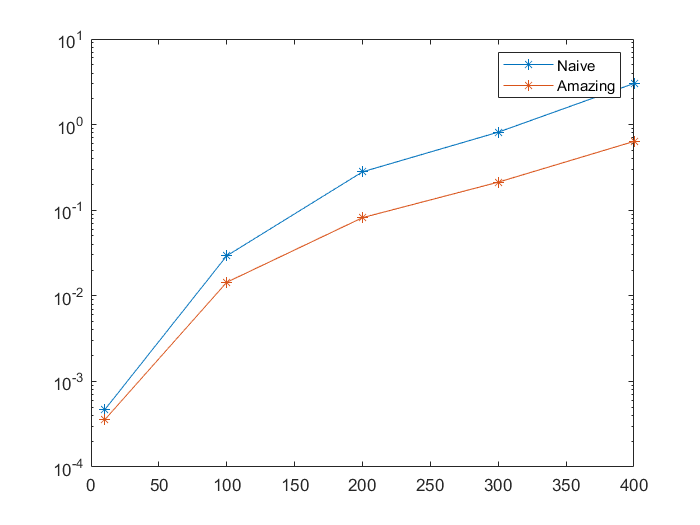



semilogy(ms, times_naive, "-*");
hold on;
semilogy(ms, times_amazing, "-*")
legend("Naive", "Amazing")